NAME = '2024-11-05'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base2 = zeros(N,1)
means_base1 = zeros(N,1)
for i = 1:N
    if i == N
        Data_base2 = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1 = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1);
        means_base2(i) = mean(Data_base2);
    else
        Data_base2 = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1 = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1);
        means_base2(i) = mean(Data_base2);
    end
end
plot(means_base1)
plot(means_base2)
%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));



%plot(Data_test_date_1,Data_test_base2_1)
%plot(Data_test_date_2,Data_test_base2_2)
mean(Data_test_base2_1)
mean(Data_test_base2_2)

plot(DATA.DATE,DATA.RHEO1)

%Руки: 79.9 - Арина, 175.7 - Паша Ч, 120.4  - Паша Р., 132.7 - Дима
%Голова: 81.8 - Арина, 67.8 - Паша Ч, 86.1 - Паша Р., 90.7 - Дима

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)
means_base2 = zeros(N,1)
std_dev_b1 = zeros(N,1)
std_dev_b2 = zeros(N,1)
for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i});
    end
end

x=1:length(TT.DATE)
data = [means_base1,means_base2];
std_data = [std_dev_b1,std_dev_b2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Средние значения базового сопротивления",'FontSize', 20)

lgd = legend(["С рук","Со лба"]);
fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Номер этапа','FontSize', 20)
grid on
grid minor
hold off

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)
means_base2 = zeros(N,1)
std_dev_b1 = zeros(N,1)
std_dev_b2 = zeros(N,1)
for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"RHEO2"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"RHEO1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        Data_date{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"RHEO2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"RHEO1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        Data_date{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i});
    end
end

x=1:7
data = [means_base1,means_base2];
std_data = [std_dev_b1,std_dev_b2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Средние значения базового сопротивления",'FontSize', 20)

lgd = legend(["С рук","Со лба"]);
fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Номер этапа','FontSize', 20)
grid on
grid minor
hold off

var1=[105.145,107.084,113.908,84.5684,101.587];
dvar1 = std(var1)

NAME = '2024-11-21'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_DATA);
amps_rheo2 = zeros(N,1)
amps_rheo1 = zeros(N,1)
for i = 1:N
    amps_rheo2(i) = max(CYCLE_BR{i}.RHEO2)-min(CYCLE_BR{i}.RHEO2);
    amps_rheo1(i) = max(CYCLE_BR{i}.RHEO1)-min(CYCLE_BR{i}.RHEO1);
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));   
end
plot(amps_rheo1)
amps_rheo11 = amps_rheo1(amps_rheo1<300);
%amps_rheo22 = amps_rheo2(4226:(4226+180));
mean(amps_rheo11)
std(amps_rheo11)
mean(amps_rheo2)
std(amps_rheo2)
%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));

NAME = '2025-03-10'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_BR);
amps_rheo2 = zeros(N,1)
amps_rheo1 = zeros(N,1)
for i = 1:N
    amps_rheo2(i) = max(CYCLE_BR{i}.RHEO2)-min(CYCLE_BR{i}.RHEO2);
    amps_rheo1(i) = max(CYCLE_BR{i}.RHEO1)-min(CYCLE_BR{i}.RHEO1);
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));   
end
plot(amps_rheo1)
amps_rheo11 = amps_rheo1(amps_rheo1<300);
%amps_rheo22 = amps_rheo2(4226:(4226+180));
mean(amps_rheo11)
std(amps_rheo11)
mean(amps_rheo2)
std(amps_rheo2)
%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_DATA);
M = length(TT.DATE);
M = 5;
means_rheo1 = zeros(M,1)
means_rheo2 = zeros(M,1)
std_dev_r1 = zeros(M,1)
std_dev_r2 = zeros(M,1)
k=1;

for i = 1:M
    for j = 1:N
        if (i == M)
            if (CYCLE_DATA{j}.NAME > TT.DATE(i))
            sum_rheo1{k} = max(CYCLE_DATA{j}.RHEO1)-min(CYCLE_DATA{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_DATA{j}.RHEO2)-min(CYCLE_DATA{j}.RHEO2);
            k = k+1;
            end
        elseif ((CYCLE_DATA{j}.NAME < TT.DATE(i+1)) && (CYCLE_DATA{j}.NAME > TT.DATE(i)))
            sum_rheo1{k} = max(CYCLE_DATA{j}.RHEO1)-min(CYCLE_DATA{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_DATA{j}.RHEO2)-min(CYCLE_DATA{j}.RHEO2);
            k = k+1;
            
        end
    end
    means_rheo1(i) = mean(cell2mat(sum_rheo1));
    std_dev_r1(i) = std(cell2mat(sum_rheo1));
    means_rheo2(i) = mean(cell2mat(sum_rheo2));
    std_dev_r2(i) = std(cell2mat(sum_rheo2));
    clear sum_rheo1 sum_rheo2;
    k = 1;
end

x=1:5
data = [means_rheo1,means_rheo2];
std_data = [std_dev_r1,std_dev_r2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off

title("Mean pulse resistance amplitude values")
lgd = legend(["Arms","Forehead"]);
fontsize(lgd,20,'points')
ylabel('Rheo, mOhm','FontSize', 20) 
xlabel('Stage number','FontSize', 20)
grid on
grid minor
hold off

%% Обработка последних экспериментов. Вычитание с башки %%

NAME = '2024-12-19'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_BR);
M = length(TT.DATE);
M = 5;
means_rheo1 = zeros(M,1)
means_rheo2 = zeros(M,1)
std_dev_r1 = zeros(M,1)
std_dev_r2 = zeros(M,1)
k=1;

for i = 1:M
    for j = 1:N
        if (i == M)
            if (CYCLE_BR{j}.NAME > TT.DATE(i))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            end
        elseif ((CYCLE_BR{j}.NAME < TT.DATE(i+1)) && (CYCLE_BR{j}.NAME > TT.DATE(i)))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            
        end
    end
    means_rheo1(i) = mean(cell2mat(sum_rheo1));
    std_dev_r1(i) = std(cell2mat(sum_rheo1));
    means_rheo2(i) = mean(cell2mat(sum_rheo2));
    std_dev_r2(i) = std(cell2mat(sum_rheo2));
    clear sum_rheo1 sum_rheo2;
    k = 1;
end

NAME = '2024-12-19'; %Название папки с данными
load(strcat('OUT/',NAME,'/CYCLE.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE);

DATE_brain = [];
ECG_brain = [];
RHEO1_brain = [];
BASE1_brain = [];
RHEO2_brain_amp = [];
BASE2_brain = [];
for i=1:N
    if (CYCLE{i}.NAME < TT.DATE(2) && ((max(CYCLE{i}.RHEO2) - min(CYCLE{i}.RHEO2))<50))
    DATE_brain = [DATE_brain; CYCLE{i}.NAME+seconds(CYCLE{i}.TIME)];
    ECG_brain = [ECG_brain; CYCLE{i}.ECG];
    RHEO1_brain = [RHEO1_brain; CYCLE{i}.RHEO1];
    BASE1_brain = [BASE1_brain; CYCLE{i}.BASE1];
    RHEO2_brain_amp = [RHEO2_brain_amp; max(CYCLE{i}.RHEO2)-min(CYCLE{i}.RHEO2)];
    BASE2_brain = [BASE2_brain; CYCLE{i}.BASE2];
    end
end

plot(RHEO2_brain_amp)
mean(RHEO2_brain_amp)
std(RHEO2_brain_amp)

plot(RHEO2_brain)

DATE_fh = [];
ECG_fh = [];
RHEO1_fh = [];
BASE1_fh = [];
RHEO2_fh = [];
BASE2_fh = [];
for i=1:N
    if ((CYCLE{i}.NAME > TT.DATE(2)) && (CYCLE{i}.NAME < TT.DATE(3)))
    DATE_fh = [DATE_fh; CYCLE{i}.NAME+seconds(CYCLE{i}.TIME)];
    ECG_fh = [ECG_fh; CYCLE{i}.ECG];
    RHEO1_fh = [RHEO1_fh; CYCLE{i}.RHEO1];
    BASE1_fh = [BASE1_fh; CYCLE{i}.BASE1];
    RHEO2_fh = [RHEO2_fh; CYCLE{i}.RHEO2];
    BASE2_fh = [BASE2_fh; CYCLE{i}.BASE2];
    end
end


plot(DATE_fh,RHEO2_fh-RHEO2_brain(1:length(RHEO2_fh)))

n1 = 72;
n2 = 12;
plot(CYCLE{n1}.TIME,CYCLE{n1}.RHEO2)
plot(CYCLE{n2}.TIME,CYCLE{n2}.RHEO2)
plot(CYCLE{n2}.TIME,CYCLE{n1}.RHEO2(1:length(CYCLE{n2}.RHEO2))-CYCLE{n2}.RHEO2)

length(CYCLE{72}.RHEO2)
length(CYCLE{10}.RHEO2)

% Построение для отношений амплитуд
NAME = '2025-02-20'; %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_amp2 = zeros(N,1)
std_dev_amp2 = zeros(N,1)
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    else
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    end
end
x=1:length(TT.DATE)
data = [means_amp2];
std_data = [std_dev_amp2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Ratio between pulse impedance amplitudes",'FontSize', 20)

%lgd = legend(["С рук","Со лба"]);
%fontsize(lgd,20,'points')
ylabel('Rheo2/Rheo1','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

NAME = '2025-02-20'; %Название папки с данными
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
means_ldf1 = mean(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(3))))

i = 2;
plot(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))))
temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))) - lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))),0.1,20);
plot(temp_ldf(abs(temp_ldf)<2))
mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20))
std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20))

hold off
NAMES = ["2025-01-24";"2025-02-04";"2025-02-13";"2025-02-20"];
NAMES(1)

% Построение для отношений амплитуд с ЛДФ

hold off
NAMES = ["2025-04-03";"2025-04-11";"2025-04-18"]; %"2025-01-24";"2025-02-04";;"2025-02-20"
for m = 1:length(NAMES)

NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_amp2 = zeros(N,1);
std_dev_amp2 = zeros(N,1);
means_ldf1 = zeros(N,1);
std_dev_ldf = zeros(N,1);
num_EC = 4;%номер этапа, где ИК и надо вырезать
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR1"));
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    elseif i ~= num_EC
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))) - lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) > 0) & (abs(DATA_LDF.MC) < 40) & (DATA_LDF.DATE_LDF > TT.DATE(i)))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf(i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    else
        means_ldf1(i) = nan;
        std_dev_ldf(i) = nan;
        means_amp2(i) = nan;
        std_dev_amp2(i) = nan;
    end
end
x=1:length(TT.DATE)
data = [means_amp2];
DATA_Means{m} = means_amp2;
DATA_std{m} = std_dev_amp2;
DATA_Means_ldf{m} = means_ldf1;
DATA_std_ldf{m} = std_dev_ldf;
% std_data = [std_dev_amp2,std_dev_ldf];
% %fig = plot(x,data,x,means_ldf)
% tiledlayout(2,1)
% ax1 = nexttile;
% errorbar(x,means_amp2,std_dev_amp2,LineWidth = 3);
% hold on
% ax2 = nexttile;
% errorbar(x,means_ldf,std_dev_ldf,LineWidth = 3);
% linkaxes([ax1 ax2],'x')% ax3

end

% hold off
% grid on

fig = figure();
set(gca,'fontsize',20)
% for i = 1:length(NAMES)
%     tiledlayout(2,1)
%     ax1 = nexttile;
%     errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
%     %hold on
%     xlabel("Surgery phase number")
%     ylabel("Amplitude ratio")
%     ax2 = nexttile;
%     errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
%     xlabel("Surgery phase number")
%     ylabel("Microcirculation parameter amplitude")
%     linkaxes([ax1 ax2],'x')% ax3
% 
% end

tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Amplitude ratio")
legend(["Patient 1", "Patient 2", "Patient 3"])
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3"])
linkaxes([ax1 ax2],'x')% ax3

% Построение для амплитуд с ЛДФ
hold off
NAMES = ["2025-01-24";"2025-02-04";"2025-02-20"]; %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_amp2 = zeros(N,1);
std_dev_amp2 = zeros(N,1);
means_ldf1 = zeros(N,1);
std_dev_ldf = zeros(N,1);
num_EC = 4;%номер этапа, где ИК и надо вырезать
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
    elseif i ~= num_EC
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
       
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))) - lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) > 0) & (abs(DATA_LDF.MC) < 40) & (DATA_LDF.DATE_LDF > TT.DATE(i)))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf(i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
    else
        means_ldf1(i) = nan;
        std_dev_ldf(i) = nan;
        means_amp2(i) = nan;
        std_dev_amp2(i) = nan;
    end
end
x=1:length(TT.DATE)
data = [means_amp2];
DATA_Means{m} = means_amp2;
DATA_std{m} = std_dev_amp2;
DATA_Means_ldf{m} = means_ldf1;
DATA_std_ldf{m} = std_dev_ldf;
% std_data = [std_dev_amp2,std_dev_ldf];
% %fig = plot(x,data,x,means_ldf)
% tiledlayout(2,1)
% ax1 = nexttile;
% errorbar(x,means_amp2,std_dev_amp2,LineWidth = 3);
% hold on
% ax2 = nexttile;
% errorbar(x,means_ldf,std_dev_ldf,LineWidth = 3);
% linkaxes([ax1 ax2],'x')% ax3

end
% hold off
% grid on
fig = figure();
fontsize(fig, 20, "points")
% for i = 1:length(NAMES)
%     tiledlayout(2,1)
%     ax1 = nexttile;
%     errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
%     %hold on
%     xlabel("Surgery phase number")
%     ylabel("Amplitude, mOhm")
%     ax2 = nexttile;
%     errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
%     xlabel("Surgery phase number")
%     ylabel("Microcirculation parameter amplitude")
%     linkaxes([ax1 ax2],'x')% ax3
% 
% end
tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Amplitude, mOhm")
legend(["Patient 1", "Patient 2", "Patient 3"])
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3"])
linkaxes([ax1 ax2],'x')% ax3

% Построение для отношений базовых с ЛДФ
hold off
NAMES = ["2025-01-24";"2025-02-04";"2025-02-20"]; %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base2 = zeros(N,1)
std_dev_b2 = zeros(N,1)
means_ldf1 = zeros(N,1);
std_dev_ldf = zeros(N,1);
for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"))./table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))) - lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) > 0) & (abs(DATA_LDF.MC) < 40) & (DATA_LDF.DATE_LDF > TT.DATE(i)))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf(i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_base2(i) = mean(Data_base2{i}./Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i}./Data_base1{i});
    end
end
x=1:length(TT.DATE)
DATA_Means{m} = means_base2;
DATA_std{m} = std_dev_b2;
DATA_Means_ldf{m} = means_ldf1;
DATA_std_ldf{m} = std_dev_ldf;
% std_data = [std_dev_amp2,std_dev_ldf];
% %fig = plot(x,data,x,means_ldf)
% tiledlayout(2,1)
% ax1 = nexttile;
% errorbar(x,means_amp2,std_dev_amp2,LineWidth = 3);
% hold on
% ax2 = nexttile;
% errorbar(x,means_ldf,std_dev_ldf,LineWidth = 3);
% linkaxes([ax1 ax2],'x')% ax3

end
fig = figure();
fontsize(fig, 20, "points")
% for i = 1:length(NAMES)
%     tiledlayout(2,1)
%     ax1 = nexttile;
%     errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
%     %hold on
%     xlabel("Surgery phase number")
%     ylabel("Amplitude ratio")
%     ax2 = nexttile;
%     errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
%     xlabel("Surgery phase number")
%     ylabel("Microcirculation parameter amplitude")
%     linkaxes([ax1 ax2],'x')% ax3
% 
% end

tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Amplitude ratio")
legend(["Patient 1", "Patient 2", "Patient 3"])
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3"])
linkaxes([ax1 ax2],'x')% ax3

% Построение для базовых с ЛДФ
hold off
NAMES = ["2025-01-24";"2025-02-04";"2025-02-20"]; %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_amp2 = zeros(N,1);
std_dev_amp2 = zeros(N,1);
means_ldf1 = zeros(N,1);
std_dev_ldf = zeros(N,1);
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
    else
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
       
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0) & (DATA_LDF.DATE_LDF > TT.DATE(i)))) - lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF < TT.DATE(i+1) & (abs(DATA_LDF.MC) > 0) & (abs(DATA_LDF.MC) < 40) & (DATA_LDF.DATE_LDF > TT.DATE(i)))),0.1,20);
        means_ldf1(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        std_dev_ldf(i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
    end
end
x=1:length(TT.DATE)
data = [means_amp2];
DATA_Means{m} = means_amp2;
DATA_std{m} = std_dev_amp2;
DATA_Means_ldf{m} = means_ldf1;
DATA_std_ldf{m} = std_dev_ldf;
% std_data = [std_dev_amp2,std_dev_ldf];
% %fig = plot(x,data,x,means_ldf)
% tiledlayout(2,1)
% ax1 = nexttile;
% errorbar(x,means_amp2,std_dev_amp2,LineWidth = 3);
% hold on
% ax2 = nexttile;
% errorbar(x,means_ldf,std_dev_ldf,LineWidth = 3);
% linkaxes([ax1 ax2],'x')% ax3

end
% hold off
% grid on
fig = figure();
fontsize(fig, 20, "points")
% for i = 1:length(NAMES)
%     tiledlayout(2,1)
%     ax1 = nexttile;
%     errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
%     hold on
%     xlabel("Surgery phase number")
%     ylabel("Amplitude, Ohm")
%     ax2 = nexttile;
%     errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
%     xlabel("Surgery phase number")
%     ylabel("Microcirculation parameter amplitude")
%     linkaxes([ax1 ax2],'x')% ax3
% 
% end
tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Amplitude, Ohm")
legend(["Patient 1", "Patient 2", "Patient 3"])
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3"])
linkaxes([ax1 ax2],'x')% ax3

figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Ratio between pulse impedance amplitudes",'FontSize', 20)

%lgd = legend(["С рук","Со лба"]);
%fontsize(lgd,20,'points')
ylabel('Rheo2/Rheo1','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

%Построение для отношений базовых импедансов
NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)
means_base2 = zeros(N,1)
std_dev_b1 = zeros(N,1)
std_dev_b2 = zeros(N,1)
for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"))./table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i}./Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i}./Data_base1{i});
    end
end
x=1:length(TT.DATE)
data = [means_base2];
std_data = [std_dev_b2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Ratio between base impedance",'FontSize', 20)

%lgd = legend(["С рук","Со лба"]);
%fontsize(lgd,20,'points')
ylabel('Base2/Base1','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

% Построение для амплитуд
NAME = '2025-02-13'; %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE) ;
means_amp2 = zeros(N,1)
std_dev_amp2 = zeros(N,1)
means_amp1 = zeros(N,1)
std_dev_amp1 = zeros(N,1)
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
        means_amp1(i) = mean(Data_amp1{i});
        std_dev_amp1(i) = std(Data_amp1{i});
    else
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i});
        std_dev_amp2(i) = std(Data_amp2{i});
        means_amp1(i) = mean(Data_amp1{i});
        std_dev_amp1(i) = std(Data_amp1{i});
    end
end
x=1:N
data = [(means_amp2/1.6)./((means_amp2/1.6) - 2.3)];%means_amp1(4:6),
std_data = [std_dev_amp2*0];%std_dev_amp1(4:6),
figure

b = bar(x,data)
hold on
for k = 1:(numel(b))                                               % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Pulse impedance amplitude mean values",'FontSize', 20)

%lgd = legend(["Transthoracic","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('Amplitude, mOhm','FontSize', 20) 
xlabel('Experimental phase number','FontSize', 20)
grid on
grid minor
hold off
std_dev_amp2(3)

%Чисто для базовых
NAME = '2025-03-13'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)
means_base2 = zeros(N,1)
std_dev_b1 = zeros(N,1)
std_dev_b2 = zeros(N,1)
for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i});
    end
end
x=1:N
data = [means_base1,means_base2];
std_data = [std_dev_b1,std_dev_b2];
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Base impedance mean values",'FontSize', 20)

lgd = legend(["Transthoracic","From forehead"]);
fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Experiment phase number','FontSize', 20)
grid on
grid minor
hold off

%Для STDH-2025 only
base1 = [53.65,132.68,69.78,65.24,61.11];
base2 = [40.26,148.7,69.11,65.24,55.06];
base3 = [33.68,150.04,55.4,63.78,55.69];
base4 = [48.04,107.94,61.12,44.00,56.58];
base5 = [55.41,95.59,42.65,31.63,53.36];
base6 = [32.13,80.02,33.00,31.99,46.45];
base7 = [26.89,74.43,33.26,55.80,44.19];
bases = [mean(base1),mean(base2),mean(base3),mean(base4),mean(base5),mean(base6),mean(base7)];
std_bases = [std(base1),std(base2),std(base3),std(base4),std(base5),std(base6),std(base7)];
x=1:7
data = bases;
std_data = std_bases;
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data (k,:), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Base impedance mean values",'FontSize', 20)

%lgd = legend(["From hands","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

%Для STDH-2025 only
pulse1 = [46.26,53.81,51.21,26.285,64.81];
pulse2 = [75.63,254.06,54.68,30.00,91.64];
pulse3 = [36.08,120.93,54.46,63.97,72.21];
pulse4 = [24.43,58.95,26.14,38.39,49.63];
pulse5 = [30.22,55.62,79.08,45.77,33.21];
pulse6 = [30.64,64.94,46.92,19.15,32.81];
pulse7 = [29.71,62.61,19.34,10.25,180.13];
amps = [mean(pulse1),mean(pulse2),mean(pulse3),mean(pulse4),mean(pulse5),mean(pulse6),mean(pulse7)];
std_amps = [std(pulse1),std(pulse2),std(pulse3),std(pulse4),std(pulse5),std(pulse6),std(pulse7)];
x=1:7
data = amps;
std_data = std_amps;
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data (k,:), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Pulse impedance amplitudes mean values",'FontSize', 20)

%lgd = legend(["From hands","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('Amplitude, mOhm','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

%Для STDH-2025 only
pulse_rat1 = [0.30,0.33,0.36,0.15,0.50];
pulse_rat2 = [0.60,1.12,0.38,0.4,0.69];
pulse_rat3 = [0.35,0.82,0.41,0.37,0.63];
base_rat4 = [0.20,0.39,0.21,0.38,0.55];
base_rat5 = [0.22,0.48,0.56,0.29,0.43];
base_rat6 = [0.31,0.61,0.43,0.17,0.45];
base_rat7 = [0.35,0.85,0.32,0.25,1.25];
amps_rat = [mean(pulse_rat1),mean(pulse_rat2),mean(pulse_rat3),mean(base_rat4),mean(base_rat5),mean(base_rat6),mean(base_rat7)];
std_amps_rat = [std(pulse_rat1),std(pulse_rat2),std(pulse_rat3),std(base_rat4),std(base_rat5),std(base_rat6),std(base_rat7)];
x=1:7
data = amps_rat;
std_data = std_amps_rat;
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data (k,:), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Pulse impedance ratio mean values",'FontSize', 20)

%lgd = legend(["From hands","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('Amplitude ratio','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

%Для STDH-2025 only
base_rat1 = [0.5,0.88,1.01,0.55,0.93];
base_rat2 = [0.39,0.99,1.01,0.55,0.84];
base_rat3 = [0.35,1.19,0.90,0.55,0.88];
base_rat4 = [0.55,0.92,1.11,0.50,1.08];
base_rat5 = [0.67,0.89,0.77,0.44,1.12];
base_rat6 = [0.42,0.83,0.65,0.50,1.11];
base_rat7 = [0.36,0.80,0.79,0.82,1.11];
base_rat = [mean(base_rat1),mean(base_rat2),mean(base_rat3),mean(base_rat4),mean(base_rat5),mean(base_rat6),mean(base_rat7)];
std_base_rat = [std(base_rat1),std(base_rat2),std(base_rat3),std(base_rat4),std(base_rat5),std(base_rat6),std(base_rat7)];
x=1:7;
data = base_rat ;
std_data = std_amps_rat;
figure

b = bar(x,data)
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data (k,:), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Base impedance ratio mean values",'FontSize', 20)

%lgd = legend(["From hands","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('Base ratio','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

По формуле Кубичека

%Расчёты по формулам для кровенаполнения
%Формула Кубичека:
%SV = l*l*rho*d_amp*t_LVET/(base*base);%l - расстояние между измерительными,
% t_LVET - время выброса = время подъёма восходящей части
clear all
hold off
l = 25*10^(-3);

NAMES = ["2025-01-24";"2025-02-04";"2025-02-20";"2025-04-03";"2025-04-11";"2025-04-18"] %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными

load(strcat('OUT/',NAME,'/PARAM.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_SV = zeros(N,1)
std_SV = zeros(N,1)
for i = 1:N
    if i == N
        Data_d_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"ad2"));
        Data_t_lvet2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"alpha2"));
        Data_base2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        HR = 1/((length(Data_d_amp2{i})-1)*0.005)*60;
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 40)));
        %temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        %means_ldf(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_ldf1(i) = mean(temp_ldf);
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        rho = 1.35;
        SV{i} = l*l.*rho.*Data_t_lvet2{i}.*Data_d_amp2{i}./(Data_base2{i}.*Data_base2{i})*1000000*HR;
        SV{i} = SV{i}( ~any( isnan( SV{i} ) | isinf( SV{i} ), 2 ),: );
        means_SV(i) = mean(SV{i});
        std_SV(i) = mean(std(SV{i}))
    else
        Data_d_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"ad2"));
        Data_t_lvet2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"alpha2"));
        Data_base2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
        HR = 1/((length(Data_d_amp2{i})-1)*0.005)*60;
        rho = 1.35;
        SV{i} = l*l.*rho.*Data_t_lvet2{i}.*Data_d_amp2{i}./(Data_base2{i}.*Data_base2{i})*1000000*HR;
        SV{i} = SV{i}( ~any( isnan( SV{i} ) | isinf( SV{i} ), 2 ),: );
        means_SV(i) = mean(SV{i});
        std_SV(i) = mean(std(SV{i}));
        if i ~= 4
        temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & DATA_LDF.DATE_LDF<TT.DATE(i+1)& (abs(DATA_LDF.MC) < 40)));
        %temp_ldf = DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0)))-lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i) & (abs(DATA_LDF.MC) < 40) & (abs(DATA_LDF.MC) > 0))),0.1,20);
        %means_ldf(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        means_ldf1(i) = mean(temp_ldf);
        std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        else
            means_ldf1(i) = nan;
            std_dev_ldf (i) = nan;
        end
    
    end
end
Data_m_SV{m} = means_SV;
Data_std_SV{m} = std_SV;
DATA_Means_ldf{m} = means_ldf1;
DATA_std_ldf{m} = std_dev_ldf;
end
x=1:N
% NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
% 
% for i = 1:length(NAMES)
% NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
% b = bar(x,Data_m_SV{i})
% fontsize(b, 20, "points")
% hold on
% for k = 1:numel(b)                                                      % Recent MATLAB Versions
%     xtips = b(k).XEndPoints;
%     ytips = b(k).YEndPoints;
%     errorbar(xtips,ytips,Data_std_SV{i}(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
% end
% title("SV from Kubicek",'FontSize', 20)
% ylabel('SV, ml/min','FontSize', 20) 
% xlabel('Surgery phase number','FontSize', 20)
% grid on
% grid minor
% saveas(b,strcat('PLOTS/',NAME,'/SV_Kubicek','.png'))
% hold off
% end


fig = figure();
fontsize(fig, 28, "points")
tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,Data_m_SV{i},Data_std_SV{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("SV, ml/min")
legend(["Patient 1", "Patient 2", "Patient 3","Patient 4", "Patient 5", "Patient 6"])
grid on
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on
    grid on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3","Patient 4", "Patient 5", "Patient 6"])
grid on
linkaxes([ax1 ax2],'x')% ax3

%то же, но по отдельности для каждого пациента

for i = 1:length(NAMES)
    NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
    fig = figure();
    fontsize(fig, 28, "points");
    tiledlayout(2,1);
    ax1 = nexttile;
    errorbar(x,Data_m_SV{i},Data_std_SV{i},LineWidth = 3);
    xlabel("Surgery phase number");
    ylabel("\DeltaV, ml/min");
    grid on
    ax2 = nexttile;
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3);
    grid on
    xlabel("Surgery phase number")
    ylabel("Microcirculation parameter amplitude")
    linkaxes([ax1 ax2],'x')% ax3
    saveas(fig,strcat('PLOTS/',NAME,'/SV_PATIENT','.fig'))
    close(fig);
end    

### Наша модель

В качестве дельта Z брать амплитуду дифференциальной реограммы умноженную на время восходящей части основной реограммы.

Тогда $\Delta V=\frac{0\ldotp 1*\Delta \rho *\rho_{\textrm{крови}} *\textrm{HR}}{\rho_{\textrm{ткани}} *\rho_{\textrm{ткани}\;\textrm{мех}} *\left(\Delta \rho -\rho_{\textrm{ткани}} \;\right)}*1000000\;$(в мл)

Где $\Delta \rho =\frac{\Delta Z}{k}$, где k - коэффициент, получаемый из модели COMSOL


$$\Delta Z=A_d *t_{\textrm{LVET}}$$
 

$A_d$ - амплитуда дифференциальной реограммы

$t_{\textrm{LVET}}$ - время восходящей части обычной реограммы

$\rho_{\textrm{крови}}$ = 1.35 Ом*м


$$\rho_{\textrm{ткани}} =\frac{Z_{\textrm{базовый}} }{k}$$


%clear all
hold off
% t_LVET - время выброса = время подъёма восходящей части

%k = 1;
%HR = 60; %WARNING!!! Нужно вычисление realtime
rho_mech_skin = 975;
rho_blood = 1.35;


NAMES = ["2025-04-03";"2025-04-11";"2025-04-18"]; %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными

[rho_skin,imp_base] = import_model(strcat('DATA/',NAME,'/model_res.txt'));

k = coeffvalues(fit(rho_skin,imp_base,'poly1'));
load(strcat('OUT/',NAME,'/PARAM.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_SV = zeros(N,1)
std_SV = zeros(N,1)
for i = 1:N
    if i == N
        Data_d_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"ad2"));
        Data_t_lvet2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"alpha2"));
        Data_base2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        %Data_d_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"ad1"));
        %Data_t_lvet1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"alpha1"));
        HR = 1/((length(Data_d_amp2{i})-1)*0.005)*60;
        delta_rho = -Data_t_lvet2{i}.*Data_d_amp2{i}/k(1)/5;%деление на 5 - преобразование единиц измерения (тут уже Ом/с)
        rho_tissue = Data_base2{i}/k(1);
        SV_BMSTU{i} = 0.1*delta_rho.*HR*rho_blood./(Data_base2{i}/k(1)*rho_mech_skin.*(delta_rho - rho_tissue))*1000000;
        SV_BMSTU{i} = SV_BMSTU{i}( ~any( isnan( SV_BMSTU{i} ) | isinf( SV_BMSTU{i} ), 2 ),: );
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_SV_BMSTU(i) = mean(SV_BMSTU{i});
        std_SV_BMSTU(i) = mean(std(SV_BMSTU{i}));

    else
        Data_d_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"ad2"));
        Data_t_lvet2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"alpha2"));
        Data_base2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
        HR = 1/((length(Data_d_amp2{i})-1)*0.005)*60;
        delta_rho = -Data_t_lvet2{i}.*Data_d_amp2{i}/k(1)/5;%деление на 5 - преобразование единиц измерения (тут уже Ом/с)
        rho_tissue = Data_base2{i}/k(1);
        SV_BMSTU{i} = 0.1*delta_rho.*HR*rho_blood./(Data_base2{i}/k(1)*rho_mech_skin.*(delta_rho - rho_tissue))*1000000;
        SV_BMSTU{i} = SV_BMSTU{i}( ~any( isnan( SV_BMSTU{i} ) | isinf( SV_BMSTU{i} ), 2 ),: );
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_SV_BMSTU(i) = mean(SV_BMSTU{i});
        std_SV_BMSTU(i) = mean(std(SV_BMSTU{i}));
    end

end
Data_m_SV_BMSTU{m} = means_SV_BMSTU;
Data_std_SV_BMSTU{m} = std_SV_BMSTU;
end

x=1:N


fontsize(fig, 20, "points")
for i = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
b = bar(x,Data_m_SV{i})
fontsize(b, 20, "points")
hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,Data_std_SV{i}(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
title("SV from BMSTU",'FontSize', 20)
ylabel('SV, ml/min','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
saveas(gcf,strcat('PLOTS/',NAME,'/SV_BMSTU','.png'))
hold off
end
% for i = 1:length(NAMES)
%     errorbar(transpose(x),Data_m_SV{i},Data_std_SV{i}, 'LineWidth',2);
%     hold on
% end
% hold off
title("SV from BMSTU",'FontSize', 20)

%lgd = legend(["Transthoracic","From forehead"]);
%fontsize(lgd,20,'points')
ylabel('SV, ml/min','FontSize', 20) 
xlabel('Surgery phase number','FontSize', 20)
grid on
grid minor
hold off

%Сравнение Кубичека и МГТУ
x = 1:N;
NAMES = ["2025-04-03";"2025-04-11";"2025-04-18"]; %"2025-01-24";
for i = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
    fig = figure();
    fontsize(fig, 28, "points");
    tiledlayout(2,1);
    ax1 = nexttile;
    errorbar(x,Data_m_SV{i+3},Data_std_SV{i+3},LineWidth = 3);
    xlabel("Surgery phase number");
    ylabel("\DeltaV, ml/min");
    grid on
    title("Kubicek equation");
    ax2 = nexttile;
    errorbar(x,Data_m_SV_BMSTU{i},Data_std_SV_BMSTU{i},LineWidth = 3);
    grid on
    xlabel("Surgery phase number")
    ylabel("\DeltaV, ml/min by 100g.")
    title("BMSTU equation");
    linkaxes([ax1 ax2],'x')% ax3
    saveas(fig,strcat('PLOTS/',NAME,'/SV_PATIENT_BMSTU','.fig'))
    close(fig);

end

Построение дельта R к R

%clear all
hold off



NAMES = ["2025-01-24";"2025-02-04";"2025-02-20";"2025-04-03";"2025-04-11";"2025-04-18"] %"2025-01-24";
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными

load(strcat('OUT/',NAME,'/PARAM.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_SV = zeros(N,1);
std_SV = zeros(N,1);
dR_R_ratio1 = zeros(N,1);
dR_R_ratio2 = zeros(N,1);
for i = 1:N
    if i == N
        Data_d_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));

        Data_base2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        dR_R_ratio2(i) = mean(Data_d_amp2{i})/mean(Data_base2{i});

        Data_d_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR1"));

        Data_base1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE1"));
        dR_R_ratio1(i) = mean(Data_d_amp1{i})/mean(Data_base1{i});

    else
        Data_d_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));

        Data_base2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
        dR_R_ratio2(i) = mean(Data_d_amp2{i})/mean(Data_base2{i});

        Data_d_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR1"));

        Data_base1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE1"));
        dR_R_ratio1(i) = mean(Data_d_amp1{i})/mean(Data_base1{i});


    end

end
Data_m_R_R1{m} = dR_R_ratio1 (~isnan(dR_R_ratio1));
Data_m_R_R2{m} = dR_R_ratio2(~isnan(dR_R_ratio2));
DATA_Means_ldf{m} = DATA_Means_ldf{m} (~isnan(DATA_Means_ldf{m}));
end

plot(Data_m_R_R1{1})
plot(Data_m_R_R2{1})

%Теперь построение этих отношений
NAMES = ["2025-01-24";"2025-02-04";"2025-02-20";"2025-04-03";"2025-04-11"];
for i = 1:length(NAMES)
    x = 1:(N-1);
    NAME = convertStringsToChars(NAMES(i)); %Название папки с данными
    fig = figure();
    fontsize(fig, 28, "points");
    tiledlayout(2,1);
    ax1 = nexttile;
    plot(x,Data_m_R_R1{i},LineWidth = 3);
    xlabel("Surgery phase number");
    ylabel("\DeltaR1/R_{base1}");
    grid on
    ax2 = nexttile;
    if (length(DATA_Means_ldf{i}) == (N-1))
    plot(x,DATA_Means_ldf{i},LineWidth = 3);
    else
        x = 2:(N-1);
        plot(x,DATA_Means_ldf{i},LineWidth = 3);
        x = 1:(N-1);
    end
    grid on
    xlabel("Surgery phase number")
    ylabel("Microcirculation parameter value")
    linkaxes([ax1 ax2],'x')% ax3
%     saveas(fig,strcat('PLOTS/',NAME,'/dR_R_ratio','.png'))
%     close(fig);
end
    

% Тестирую фильтрацию ЛДФ


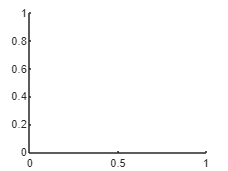

% Новые вычисления
clear all
fpass = [0.6,1.6];
%fpass=3;
hold off
NAMES = ["2025-04-03";"2025-04-11";"2025-04-18";"2025-05-29";"2025-07-04";"2025-07-10";"2025-07-16";"2025-07-30";"2025-08-14";"2025-08-28"];
ldf_fl = ones(length(NAMES));%ЛДФ есть

for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
[rho_skin, base_imp] = import_model(strcat('DATA/',NAME,'/model_res.txt'), [6, Inf]);
res = coeffvalues(fit(rho_skin,base_imp,'poly1'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);

% Чтение исходных данных циклов

    load(strcat('OUT/',NAME,'/CYCLE_DATA.mat'));
    load(strcat('OUT/',NAME,'/PARAM.mat'));
try
    load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
catch ME
    ldf_fl(m) = 0;
end
N = length(TT.DATE);
dV = zeros(N-1,1);
means_dV = zeros(N-1,1);
std_dV = zeros(N-1,1);

for i = 1:N
    if (i ~= 4)
    if i == N
        size{m}(i) = 0;
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        if (ldf_fl(m))
            temp_ldf = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass,20);
            temp_ldf = movmax(temp_ldf(abs(temp_ldf)<10),20)-movmin(temp_ldf(abs(temp_ldf)<10),20)
            
            means_ldf(i) = mean(temp_ldf);
            data2{(m-1)*N+i} = temp_ldf;
            
            std_dev_ldf (i) = std(temp_ldf);
        end
        clear Data_cycle;
        idx = 1;
        for j = 1:length(CYCLE_DATA)
            
            if (CYCLE_DATA{j}.NAME > TT.DATE(i))
                Data_cycle{idx} = CYCLE_DATA{j};
                size{m}(i) = size{m}(i)+length(Data_cycle{idx});
                idx = idx+1;
            end
        end
        Data_cycle = pre_filt(Data_cycle);
        [Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,T,dZ,dV] = params_new(Data_cycle,res(1),res(2));
        data3{(m-1)*N+i} = Data_amp2{i}./Data_amp1{i};
        data1{(m-1)*N+i} = abs(dV);
        means_dV(i) = mean(dV);
        std_dV(i) = std(dV);
    else
        size{m}(i) = 0;
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
        if (ldf_fl(m))
            temp_ldf = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass,20);
            temp_ldf = movmax(temp_ldf(abs(temp_ldf)<10),20)-movmin(temp_ldf(abs(temp_ldf)<10),20);
            means_ldf(i) = mean(temp_ldf);
            data2{(m-1)*N+i} = temp_ldf;
            std_dev_ldf (i) = std(temp_ldf);
            %std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        end
        clear Data_cycle;
        idx = 1;
        for j = 1:length(CYCLE_DATA)
            
            if (CYCLE_DATA{j}.NAME < TT.DATE(i+1) && (CYCLE_DATA{j}.NAME > TT.DATE(i)))
                Data_cycle{idx} = CYCLE_DATA{j};
                size{m}(i) = size{m}(i)+length(Data_cycle{idx});
                idx = idx+1;
            end
        end   
            
        Data_cycle = pre_filt(Data_cycle);
        [Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,T,dZ,dV] = params_new(Data_cycle,res(1),res(2));
        data1{(m-1)*N+i} = abs(dV);
        data3{(m-1)*N+i} = Data_amp2{i}./Data_amp1{i};
        means_dV(i) = mean(dV);
        
        std_dV(i) = std(dV);
        
    
    end
    end
end


if (length(means_dV) >= 4)
    means_dV(4) = [];
    std_dV(4) = [];
    if(ldf_fl(m))
        means_ldf(4) = [];
        std_dev_ldf(4) = [];
    end
end
if(ldf_fl(m))
    DATA_Means_ldf{m} = means_ldf;
    DATA_std_ldf{m} = std_dev_ldf;
end
dV_mean{m} = abs(means_dV);
dV_std{m} = std_dV;
end

temp_ldf =     4.1378
    4.9683
    5.5277
    5.8035
    5.8389
    5.8389
    5.8389
    5.8389
    5.8389
    5.8389


temp_ldf =     5.6202
    6.4180
    7.4618
    8.1461
    8.4731
    8.5024
    8.5024
    8.5024
    8.5024
    8.5024


temp_ldf =    13.3802
   13.3802
   13.3802
   13.3802
   13.3802
   13.3802
   13.3802
   13.3802
   13.3802
   13.3802


temp_ldf =     5.8410
    7.0234
    7.8233
    8.2214
    8.2774
    8.2774
    8.2774
    8.2774
    8.2774
    8.2774


temp_ldf =     4.7674
    5.7674
    6.5301
    6.9651
    7.1078
    7.1078
    7.1078
    7.1078
    7.1078
    7.1078


temp_ldf =     0.6614
    0.8020
    0.8884
    0.9139
    0.9139
    0.9139
    0.9139
    0.9139
    0.9139
    0.9139


temp_ldf =     7.7312
    9.5016
   10.7750
   11.4747
   11.6318
   11.6318
   11.6318
   11.6318
   11.6318
   11.6318


temp_ldf =     6.1525
    7.4061
    8.2616
    8.6989
    8.7802
    8.7802
    8.7802
    8.7802
    8.7802
    8.7802


temp_ldf =     0.1870
    0.1870
    0.1870
    0.1870
    0.1870
    0.2227
    0.2726
    0.2949
    0.2949
    0.2949


temp_ldf =     4.7008
    5.7629
    6.5273
    6.9601
    7.0931
    7.0931
    7.0931
    7.0931
    7.0931
    7.0931


% Играемся со статистической значимостью
clear data_all_dV data_all_dR_R data_all_ldf
for i=1:60
    data1{i} = transpose(data1{i});
end
data_all_dV{1} = [data1{1};data1{7};data1{13};data1{19};data1{25};data1{31};data1{37};data1{43};data1{49};data1{55}];
data_all_dV{2} = [data1{2};data1{8};data1{14};data1{20};data1{26};data1{32};data1{38};data1{44};data1{50};data1{56}];
data_all_dV{3} = [data1{3};data1{9};data1{15};data1{21};data1{27};data1{33};data1{39};data1{45};data1{41};data1{57}];
data_all_dV{4} = [data1{5};data1{11};data1{17};data1{23};data1{29};data1{35};data1{41};data1{47};data1{53};data1{59}];
data_all_dV{5} = [data1{6};data1{12};data1{18};data1{24};data1{30};data1{36};data1{42};data1{48};data1{54};data1{60}];

data_all_dR_R{1} = [data3{1};data3{7};data3{13};data3{19};data3{25};data3{31};data3{37};data3{43};data3{49};data3{55}];
data_all_dR_R{2} = [data3{2};data3{8};data3{14};data3{20};data3{26};data3{32};data3{38};data3{44};data3{50};data3{56}];
data_all_dR_R{3} = [data3{3};data3{9};data3{15};data3{21};data3{27};data3{33};data3{39};data3{45};data3{41};data3{57}];
data_all_dR_R{4} = [data3{5};data3{11};data3{17};data3{23};data3{29};data3{35};data3{41};data3{47};data3{53};data3{59}];
data_all_dR_R{5} = [data3{6};data3{12};data3{18};data3{24};data3{30};data3{36};data3{42};data3{48};data3{54};data3{60}];

data_all_ldf{1} = [data2{1};data2{7};data2{13};data2{19};data2{25};data2{31};data2{37};data2{43};data2{49};data2{55}];
data_all_ldf{2} = [data2{2};data2{8};data2{14};data2{20};data2{26};data2{32};data2{38};data2{44};data2{50};data2{56}];
data_all_ldf{3} = [data2{3};data2{9};data2{15};data2{21};data2{27};data2{33};data2{39};data2{45};data2{41};data2{57}];
data_all_ldf{4} = [data2{5};data2{11};data2{17};data2{23};data2{29};data2{35};data2{41};data2{47};data2{53};data2{59}];
data_all_ldf{5} = [data2{6};data2{12};data2{18};data2{24};data2{30};data2{36};data2{42};data2{48};data2{54};data2{60}];


for i=0:9
    pat_dV{i+1,1} = data1{i*6+1};
    pat_dV{i+1,2} = data1{i*6+2};
    pat_dV{i+1,3} = data1{i*6+3};
    pat_dV{i+1,4} = data1{i*6+5};
    pat_dV{i+1,5} = data1{i*6+6};

end

clear data_no_outliers
values = [];
groups = [];
n = 8;
data = pat_dV{n};

Undefined variable 'pat_dV'.

data_no_outliers = cell(5);

for i = 1:5
    currentData = pat_dV{n,i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:5
    currentData = data_no_outliers{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Surgery stage','FontSize', 18);
ylabel('${\Delta V}$', 'Interpreter', 'latex','FontSize', 18)
grid on
xticks(1:5);
for i=1:5
    if i<5
    [ps_dV1(i), hs_dV1(i), stats] = ranksum(data_no_outliers{i}, data_no_outliers{i+1});
    end
end
%3,4 not ok, 2,9,10 ok 1,5,6,7,8 semi ok

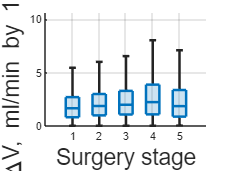

data = data_all_dV;
data_no_outliers = cell(5);

for i = 1:length(data)
    currentData = data{i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:length(data)
    currentData = data_no_outliers{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Surgery stage','FontSize', 18);
ylabel('\DeltaV, ml/min by 100g', 'FontSize', 18)
grid on
xticks(1:5);

%data_all_dV = data_no_outliers;

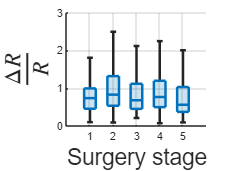

data = data_all_dR_R;
data_no_outliers = cell(5);

for i = 1:length(data)
    currentData = data{i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:length(data)
    currentData = data_no_outliers{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Surgery stage','FontSize', 18);
ylabel('$\frac{\Delta R}{R}$', 'Interpreter', 'latex','FontSize', 18)
grid on
xticks(1:5);

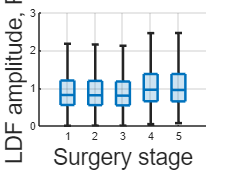

data = data_all_ldf;
data_no_outliers = cell(5);

for i = 1:length(data)
    currentData = data{i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:length(data)
    currentData =data_no_outliers{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Surgery stage','FontSize', 18);
ylabel('LDF amplitude, PU','FontSize', 18)
grid on
xticks(1:5);

% Статистика для dV
medians_dV= zeros(1,5);
means_dV= zeros(1,5);
Q1s_dV= zeros(1,5);
Q3s_dV= zeros(1,5);
ps_dV = zeros(1,4);
hs_dV = zeros(1,4);

for i=1:5
    means_dV(i) = mean(data_all_dV{i});
    medians_dV(i) = median(data_all_dV{i});
    Q1s_dV(i) = quantile(data_all_dV{i},0.25);
    Q3s_dV(i) = quantile(data_all_dV{i},0.75);
    if i<5
    [ps_dV(i), hs_dV(i), stats] = ranksum(data_all_dV{i}, data_all_dV{i+1});
    end
end

% Статистика для dR_R
medians_dR_R= zeros(1,5);
means_dR_R= zeros(1,5);
Q1s_dR_R= zeros(1,5);
Q3s_dR_R= zeros(1,5);
ps_dR_R = zeros(1,4);
hs_dR_R = zeros(1,4);

for i=1:5
    means_dR_R(i) = mean(data_all_dR_R{i});
    medians_dR_R(i) = median(data_all_dR_R{i});
    Q1s_dR_R(i) = quantile(data_all_dR_R{i},0.25);
    Q3s_dR_R(i) = quantile(data_all_dR_R{i},0.75);
    if i<5
    [ps_dR_R(i), hs_dR_R(i), stats] = ranksum(data_all_dR_R{i}, data_all_dR_R{i+1});
    end
end

% Статистика для ЛДФ
medians_ldf= zeros(1,5);
means_ldf= zeros(1,5);
Q1s_ldf= zeros(1,5);
Q3s_ldf= zeros(1,5);
ps_ldf = zeros(1,4);
hs_ldf = zeros(1,4);

for i=1:5
    means_ldf(i) = mean(data_all_ldf{i});
    medians_ldf(i) = median(data_all_ldf{i});
    Q1s_ldf(i) = quantile(data_all_ldf{i},0.25);
    Q3s_ldf(i) = quantile(data_all_ldf{i},0.75);
    if i<5
    [ps_ldf(i), hs_ldf(i), stats] = ranksum(data_all_ldf{i}, data_all_ldf{i+1});
    end
end

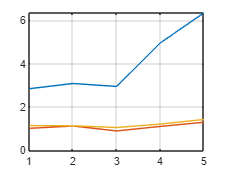

plot(means_dV)
hold on
plot(means_dR_R)
plot(means_ldf)
hold off
grid on

corrcoef(means_dR_R,means_dV)

ans =     1.0000    0.7156
    0.7156    1.0000


corrcoef(means_dV,means_ldf)

ans =     1.0000    0.9200
    0.9200    1.0000


corrcoef(means_dR_R,means_ldf)

ans =     1.0000    0.8979
    0.8979    1.0000


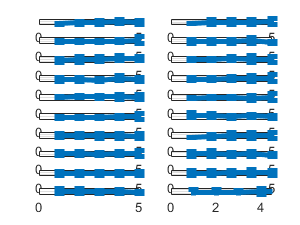

NAMES = ["2025-04-03";"2025-04-11";"2025-04-18";"2025-05-29";"2025-07-04";"2025-07-10";"2025-07-16";"2025-07-30";"2025-08-14";"2025-08-28"];
fig = figure();
pos = [1,3,5,7,9,11,13,15,17,19,2,4,6,8,10,12,14,16,18,20];
%pos = [1,3,5,7,2,4,6,8];
fontsize(fig, 28, "points");
for i = 0:(length(NAMES)-1)
    subplot(10,2,pos(2*i+1));
    errorbar(x,dV_mean{i+1},dV_std{i+1},LineWidth = 3);
    ylabel("\DeltaV,ml/min");
    grid on
    subplot(10,2,pos(2*(i)+2));
    errorbar(x,DATA_Means_ldf{i+1},DATA_std_ldf{i+1},LineWidth = 3);
    ylabel("PU")
    grid on
end

% Усреднение среднего
NAMES = ["2025-04-03";"2025-04-11";"2025-04-18";"2025-05-29";"2025-07-04";"2025-07-10";"2025-07-16";"2025-07-30";"2025-08-14"];
fig = figure();

fontsize(fig, 28, "points");
tiledlayout(2,1);
for k = 1:length(NAMES)
    means{1}(k) = dV_mean{k}(1);
    means{2}(k) = dV_mean{k}(2);
    means{3}(k) = dV_mean{k}(3);
    means{4}(k) = dV_mean{k}(4);
    means{5}(k) = dV_mean{k}(5);
    stds{1}(k) = dV_std{k}(1);
    stds{2}(k) = dV_std{k}(2);
    stds{3}(k) = dV_std{k}(3);
    stds{4}(k) = dV_std{k}(4);
    stds{5}(k) = dV_std{k}(5);
    sizes{1}(k) = size{k}(1);
    sizes{2}(k) = size{k}(2);
    sizes{3}(k) = size{k}(3);
    sizes{4}(k) = size{k}(5);
    sizes{5}(k) = size{k}(6);

    means_ldf1{1}(k) = DATA_Means_ldf{k}(1);
    means_ldf1{2}(k) = DATA_Means_ldf{k}(2);
    means_ldf1{3}(k) = DATA_Means_ldf{k}(3);
    means_ldf1{4}(k) = DATA_Means_ldf{k}(4);
    means_ldf1{5}(k) = DATA_Means_ldf{k}(5);
    stds_ldf1{1}(k) = DATA_std_ldf{k}(1);
    stds_ldf1{2}(k) = DATA_std_ldf{k}(2);
    stds_ldf1{3}(k) = DATA_std_ldf{k}(3);
    stds_ldf1{4}(k) = DATA_std_ldf{k}(4);
    stds_ldf1{5}(k) = DATA_std_ldf{k}(5);

end
%Получение массива средних и СКО по этапам
for i=1:5
    fin_mean(i) = mean(means{i});
    fin_std(i) = calculate_pooled_stdev(means{i},stds{i},sizes{i});
    fin_mean_ldf(i) = mean(means_ldf1{i});
    fin_std_ldf(i) = calculate_pooled_stdev(means_ldf1{i},stds_ldf1{i},sizes{i}/10);
end
x = 1:5;
ax1 = nexttile;
errorbar(x,fin_mean,fin_std,LineWidth = 3);
grid on
xlabel("Surgery stage number")
ylabel("\DeltaV, ml/min")
ax2 = nexttile;
errorbar(x,fin_mean_ldf,fin_std_ldf,LineWidth = 3);
grid on
xlabel("Surgery stage number")
ylabel("PU")
linkaxes([ax1 ax2],'x')% ax3

test = DATA_Means_ldf{k}(1);

%Зависимости от введенных доз пропофола в мг
prop_doses{1} = [90;20;800;0;0];
prop_doses{2} = [140;20;600;0;0];
prop_doses{3} = [140;0;600;0;0];
prop_doses{4} = [140;0;0;0;0];
prop_doses{5} = [160;0;0;0;0];
prop_doses{6} = [130;600;0;400;0];
prop_doses{7} = [];
prop_doses{8} = [];
prop_doses{9} = [];


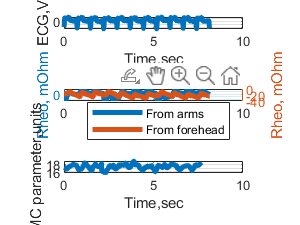

%Зависимости от введенных доз фентанила в мг
phent_doses{1} = [0.1;1.3;0;0;0];
phent_doses{2} = [0.2;2.2;0;0;0];

phent_doses{3} = [0.2;1.2;0;0;0];
phent_doses{4} = [];
phent_doses{5} = [0.2;1];
phent_doses{6} = [];
phent_doses{7} = [];
phent_doses{8} = [];
phent_doses{9} = [];

clear data_drheo1 drheo1
%Рисунок для показания как считать
fig = figure();
nstart = 2201;
nend = 2201;
last_time = 0;
last_time_ldf = 0;
data_time = [];
data_ecg = [];
data_rheo1 = [];
data_drheo1 = [];
data_rheo2= [];


val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));
time =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));

data_ldf = [];
time_ldf = [];
for i=(nstart):nend
    
    data_time = [data_time;(CYCLE_DATA{i}.TIME+last_time)];
    last_time = max(data_time);
    data_ecg = [data_ecg;CYCLE_DATA{i}.ECG];
    data_rheo1 = [data_rheo1;-CYCLE_DATA{i}.RHEO1];
    
    drheo1 = zeros(length(CYCLE_DATA{i}.TIME),1);
    for j = 2:length(CYCLE_DATA{i}.TIME)
        drheo1(j) = (-CYCLE_DATA{i}.RHEO1(j) - (-CYCLE_DATA{i}.RHEO1(j-1)))*10^(-3)/0.005;
    end
    

    data_drheo1 = [data_drheo1;drheo1];
    data_rheo2 = [data_rheo2;-CYCLE_DATA{i}.RHEO2];
    
    val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));
    time =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));

    data_ldf = [data_ldf;val];
    time_ldf = [time_ldf;time-time(1)+last_time_ldf];
    last_time_ldf = max(time_ldf);

end
fontsize(fig, 28, "points");

tiledlayout(3,1);


ax1 = nexttile;
plot(data_time,data_rheo1,LineWidth = 3);
ylabel("Rheo, mOhm");
grid on
title("From arms");
ax3 = nexttile;
plot(data_time,data_drheo1,LineWidth = 3);
xlabel("Time,sec");
ylabel("dRheo, Ohm/s");
title("Differential from arms");
grid on
ax3 = nexttile;
plot(data_time,data_rheo2,LineWidth = 3);
xlabel("Time,sec");
ylabel("Rheo, mOhm");
title("From forehead");
grid on
%legend(["From arms","From forehead"]);

linkaxes([ax1,ax2,ax3],'x')% ax3
%xlim([0,10]);